# 生产噪声当作数据集

mu1=[0 0];  %均值
S1=[0.1 0 ; 0 0.1];  %协方差
data1=mvnrnd(mu1,S1,100);   %产生高斯分布数据
%%第二组数据
mu2=[-1.25 1.25];
S2=[0.1 0 ; 0 0.1];
data2=mvnrnd(mu2,S2,100);
%%第三组数据
mu3=[1.25 1.25];
S3=[0.1 0 ; 0 0.1];
data3=mvnrnd(mu3,S3,100);
%%显示数据
figure
plot(data1(:,1),data1(:,2),'b+');
hold on;
plot(data2(:,1),data2(:,2),'b+');
plot(data3(:,1),data3(:,2),'b+');


%%初始化变量
data = [data1;data2;data3];
num = data;
gg = mrgcdemo3(num,16);

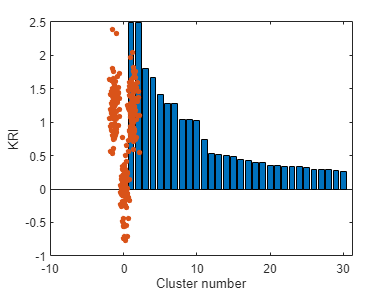

scatter(num(:,1),num(:,2),20,'filled')

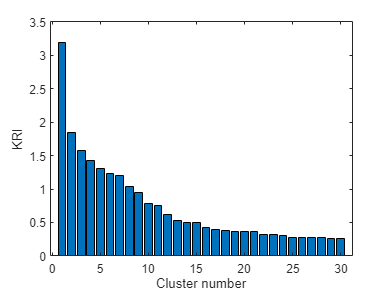

tic;
gg = mrgcdemo3(num,19);

toc

历时 2.569439 秒。


disp(['运行时间: ',num2str(toc)]);

运行时间: 2.571


## 读取excel，实际井作数据集（注意需要数据归一化）

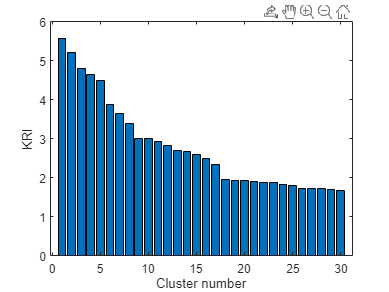

[num,txt,raw]=xlsread('C:\Users\UPC\Desktop\义282.xlsx') ; % num为我们要处理的数据
gg = mrgcdemo1(num,9);



li = zeros(length(num),1);
for i = 1:length(gg)
    li(cell2mat(gg(i))) = i;
end

## 可视化 1:AC 2:CNL 3:DEN 4:GR 5:LLD 6:LLS 7:MSFL 8:SP 9:CAL

sz = 18;
s1=1;
s2=2;
figure
hold on;

scatter(num(cell2mat(gg(1,3)),s1),num(cell2mat(gg(1,3)),s2),sz,"cyan","filled");
scatter(num(cell2mat(gg(1,1)),s1),num(cell2mat(gg(1,1)),s2),sz,"black","filled");
scatter(num(cell2mat(gg(1,2)),s1),num(cell2mat(gg(1,2)),s2),sz,"blue","filled");
scatter(num(cell2mat(gg(1,4)),s1),num(cell2mat(gg(1,4)),s2),sz,"green","filled");
scatter(num(cell2mat(gg(1,6)),s1),num(cell2mat(gg(1,6)),s2),sz,"red","filled");
scatter(num(cell2mat(gg(1,5)),s1),num(cell2mat(gg(1,5)),s2),sz,"magenta","filled");
scatter(num(cell2mat(gg(1,7)),s1),num(cell2mat(gg(1,7)),s2),sz,"yellow","filled");
scatter(num(cell2mat(gg(1,8)),s1),num(cell2mat(gg(1,8)),s2),sz,"black",'s',"filled");
scatter(num(cell2mat(gg(1,9)),s1),num(cell2mat(gg(1,9)),s2),sz,"red",'s',"filled");

title('mrgc');

## 自动类别可视化

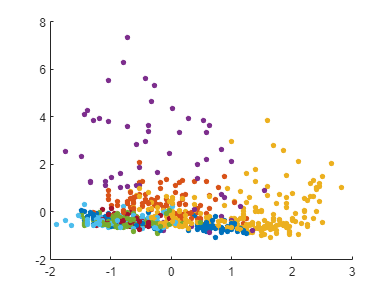

[m,n] = size(num);
data4 = zeros(m,1);
for i = 1:length(gg)
    data4(cell2mat(gg(1,i))) = i;
end
figure;
scatter(num(:,2),num(:,5),20,data4,'filled');
colormap("lines");

## Kmeans

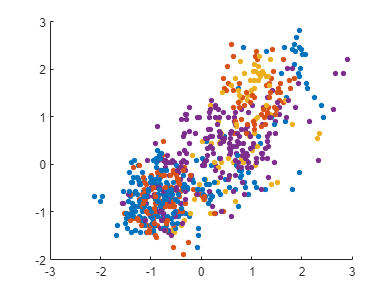

[idx1,C] = kmeans(num,10); %聚类
number1 = length(unique(idx1)); %聚类个数
%-------------------------------------------------------------------------
figure;
scatter(num(:,1),num(:,2),20,idx1,'filled');
colormap("lines");

## dbscan

[idx, corepts] = dbscan(num,1,3);
number = length(unique(idx));%聚类个数
figure;
scatter(num(:,1),num(:,2),20,idx,'filled');
colormap("turbo");
title('Dbscan');

rng('default') % For reproducibility

% Parameters for data generation
N = 300;  % Size of each cluster
r1 = 0.5; % Radius of first circle
r2 = 5;   % Radius of second circle
theta = linspace(0,2*pi,N)';

X1 = r1*[cos(theta),sin(theta)]+ rand(N,1); 
X2 = r2*[cos(theta),sin(theta)]+ rand(N,1);
X = [X1;X2]; % Noisy 2-D circular data set

scatter(X(:,1),X(:,2),20,'filled')

gg1 = mrgcdemo3(X,30);

[m,n] = size(X);
data4 = zeros(m,1);
for i = 1:length(gg1)
    data4(cell2mat(gg1(1,i))) = i;
end
figure;
scatter(X(:,1),X(:,2),20,data4,'filled');
colormap("lines");


gg2 = mrgcdemo1(X,60);

[m,n] = size(X);
data4 = zeros(m,1);
for i = 1:length(gg2)
    data4(cell2mat(gg2(1,i))) = i;
end
figure;
scatter(X(:,1),X(:,2),20,data4,'filled');
colormap("lines");


[idx1,C] = kmeans(X,2); %聚类
number1 = length(unique(idx1)); %聚类个数
%-------------------------------------------------------------------------
figure;
scatter(X(:,1),X(:,2),20,idx1,'filled');
colormap("lines");
